r0=[0 0 0]/4;
r1=[1 1 0]/4;
r2=[1 0 1]/4;
r3=[0 1 1]/4;
global rs kb
rs = cat(1, r0,r1,r2,r3)'

rs =          0    0.2500    0.2500         0
         0    0.2500         0    0.2500
         0         0    0.2500    0.2500


kb = 0.0862

kb = 0.0862

ans =     0.5000    1.0000    1.0000


ans = 118.0834

SqPowder0(2,-1,7.8)

ans = 0.5050

x = [0.1:0.1:5]*10.5;
sqs = zeros(1,50);
tic
for i=1:50
    sqs(i) = SqPowder0(x(i), -1, 7.8);
end
toc

Elapsed time is 126.033864 seconds.


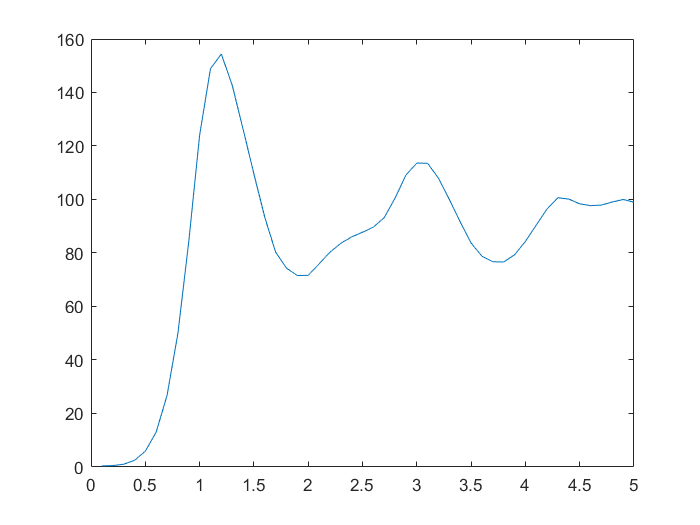

T = 1×2 table
          Q               Sq      
    _____________    _____________

    [1×50 double]    [1×50 double]


figure
plot(x/10.5, sqs)

% Create a table with the data and variable names
T = table(x'/10.5, sqs', 'VariableNames', { 'Q', 'Sq'} )

T = 50×2 table
     Q       Sq   
    ___    _______

    0.1    0.40549
    0.2    0.52692
    0.3     1.0276
    0.4     2.4694
    0.5     5.8903
    0.6     13.067
    0.7     26.697
    0.8     49.936
    0.9     84.175
      1     123.99
    1.1     148.89
    1.2      154.4
    1.3     142.79
    1.4      126.4
    1.5     109.54
    1.6     93.359


% Write data to text file
writetable(T, 'D:\2_Neutron_scattering\2_D7_ILL_Gd2Hf2O7_Feb2020\MF_Sq_matlab.txt')

## Define functionws

function output=Sq0(Q, Jex, T)
    global rs kb
    phase = 2*real(transpose(exp(1i* Q*rs)) * exp(-1i * Q*rs) );
    phase = phase - diag(diag(phase));
    [vec, val] = eig(Jex.*phase);
    val = diag(val);
    output = sum(sum(vec,1).^2 ./ (3*T*kb - val'));
end

function output = SqPolar0(q, theta, phi, Jex, T)
    output = Sq0(q.*[sin(theta).*cos(phi), sin(theta).*sin(phi), cos(theta)], Jex, T);
end
% "ArrayValued"=True: prevent setting arrays of the and phi which Sq does not
% accept
function output = SqPowder0(q, Jex, T)
    output = integral(@(the) integral(@(phi)SqPolar0(q, the, phi, Jex, T)*sin(the),0, pi/4,"ArrayValued",true), 0, pi/2,"ArrayValued",true); 
end

% integral2: set 2d array of the and phi which is not supported by Sq. We should make Sq accept them.
% not completed yet
function output=Sq(Q, Jex, T)
    global rs kb
    display(Q);
    p1 = exp(1i* pagefun(mtimes, Q,rs));
    p2 = exp(-1i* pagefun(mtimes, Q,rs));
    phase = 2*real(permute(p1, [2,1,3]) * p2);
    phase = phase - diag(diag(phase));
    [vec, val] = eig(Jex.*phase);
    val = diag(val);
    output = sum(sum(vec,1).^2 ./ (3*T*kb - val'));
end

function output = SqPolar(q, theta, phi, Jex, T)
    display(q);
    display(theta);
    display(phi);
    output = Sq(q.*permute(cat(3, sin(theta).*cos(phi), sin(theta).*sin(phi), cos(theta)),[1,3,2]), Jex, T);
end

function output = SqPowder(q, Jex, T)
    %fun = @(q, the, phi) Sq(q*[sin(the)*cos(phi), sin(the)*sin(phi), cos(the)], Jex, T)*sin(the);
    output = integral2(@(the, phi)SqPolar(q, the, phi, Jex, T), 0, pi/2, 0, pi/4); 
end

